# Lab1: フーリエ級数

[⇦ メインメニューに戻る](matlab:open('../MainMenu.mlx'))

**1.** フーリエ正弦級数を考えます:


$$f(t) = \sum_{n=1}^\infty b_n \sin \left(  2 \pi    t \right)$$


[Sine and Cosine Series アプリ](matlab: SinCosSeries)を開き、右上のボタンで基底を**sine**に設定してください。左側の係数を調整して、下図の関数 $f$ を生成する $b_2$ と $b_4$ の値を求めてください。0.5単位で四捨五入し、下に答えを記録してください。他の係数はゼロです。

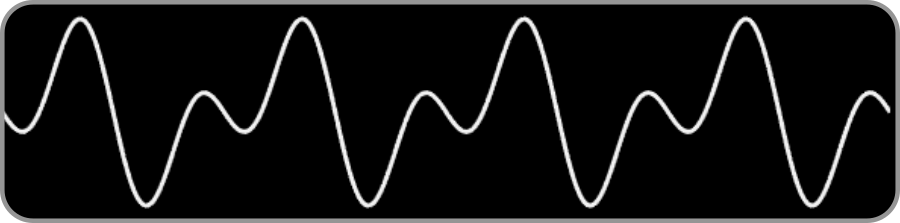

% Replace the NaNs with your answers
Q1_b2 = 1;
Q1_b4 = -1;

**2.** 位相シフトしたcosineを考えます:


$$g(t) = 1.4\cos(4 \pi t  - \pi/4 )$$


[Magnitude and Phase アプリ](matlab: run MagnitudePhase.mlapp)を使って、フーリエ級数でこの関数を再現してください。

**a.** ”振幅および位相で表現するフーリエ級数”（アプリ右側）を使ってください。この関数を再現する $A_2$ と $\phi_2$ の値は何ですか？

Q2_A2 = NaN;
Q2_phi2 = NaN;

**b.** "sinおよびcosで表現するフーリエ級数"（アプリ左側）を使ってください。この関数を再現する $a_2$ と $b_2$ の値は何ですか？0.1単位で四捨五入してください。

Q2_a2 = NaN;
Q2_b2 = NaN;

**タスク.** 以下の3から5では、オーディオ信号のデータを使用します。このセクションを実行してデータを読み込み、フーリエ級数係数を計算してください。

[y,Fs] = audioread("SynthesizedSound.mp4"); % Read the data
sound(y,Fs) % Play the sound
plot(y) % Plot the data
ylabel("y")
[freq,a,b] = computeFourierCoef(y',Fs); % Compute series coef.

**3.** フーリエ係数の振幅と位相を計算してください。係数はベクトル `a` と `b` に格納されています。結果を `A` と `phi` に保存してください。

**ヒント:** 位相の計算には [`atan2`](https://www.mathworks.com/help/matlab/ref/atan2.html) を使ってください。

A = NaN;
phi = NaN;

**4.** 振幅ベクトル `A` を周波数ベクトル `freq`（単位はHz）に対してプロットしてください。横軸の範囲を`[0 200]` Hz  に設定し、軸ラベルも付けてください。

% Write your code here
plot(freq,A)
xlim([0 200])
xlabel("Frequency (Hz)")
ylabel("Magnitude")

**5.** 周波数領域にはいくつかの明確なピークがあります。ピークの周波数（Hz）はいくつですか？

% Record your answers in the vector freqPeaks
% e.g., freqPeaks = [2 5 10]
freqPeaks = [100 120 150];

**6.** 次の形のオーディオ信号を作成してください


$$x(t) = \sum_{n=1}^3 b_n \sin\left(2 \pi f_n t\right)$$


ただし、項は3つだけで、上記**5**で特定したピークの周波数を使います。最も高い周波数の係数は0.1、他の2つの低い周波数の係数は0.2に設定してください。

変数 `t` を使って信号 `x` を定義してください。

t = 0:1/Fs:3; % Use this variable
% Write your code here
x = 0.1*sin(2*pi*150*t) + 0.2*sin(2*pi*120*t) + 0.2*sin(2*pi*100*t);

**7.** 信号 $x$ を $t$ に対してプロットしてください。

plot(t,x)
xlabel("t (s)")
ylabel("x")

**8.** [`sound`](https://www.mathworks.com/help/matlab/ref/sound.html) 関数を使って信号 $x$ をオーディオとして再生してください。

sound(x,Fs)

**9.** 下の行のコメントを外して `x` のフーリエ係数を計算してください。その後、係数の振幅を計算し、その値を `Ax` に保存してください。

[freq,a,b] = computeFourierCoef(x,Fs);
Ax = sqrt(a.^2 + b.^2);

**10.** 振幅ベクトル `Ax` を周波数ベクトル `freq`（単位はHz）に対してプロットしてください。横軸の範囲を `[0 200]` Hz に設定してください。

plot(freq,Ax)
xlim([0 200])
xlabel("Frequency (Hz)")
ylabel("Magnitude")

**11.** 元の信号 $y$ と、3つの周波数だけを使って作成した信号 $x$ を比較してください。

- similarity: 2つの信号$y$ と$x$ の間にどのような類似点が見られますか？

- difference: 2つの信号$y$ と$x$ の主な違いは何ですか？

% Record your answers below in the quotes.
similarity = "Similar frequency content."
difference = "No amplitude modulation in x(t)."

[⇦ メインメニューに戻る](matlab:open('../MainMenu.mlx'))

function [freq,a,b] = computeFourierCoef(y,Fs)
% This helper function computes the Fourier coefficients
% of a signal y(t) with sampling frequency Fs

    % FFT
    Y = fft(y);

    % Fourier series coefficients from the FFT
    N = numel(y);
    Nterms = round(N/2);
    YHalf = Y(2:Nterms);
    a0 = real(Y(1))/N;
    a = [a0,2/N*real(YHalf)];
    b = [0,-2/N*imag(YHalf)];

    % The frequencies of the coefficients
    freq = Fs/N*(0:(Nterms-1))';
end
